Séance 1 - TP /Projet - MSA

Bachelard - Laleu

clear all

Nu0 = 0.05;
N = 256;
VectN = 1:256;
sigmaCarre = 0.5;
a=0.5; % coefficient du filtre AR1

Sin = SinPalea(Nu0, 2, N)

Sin =     1.4868    1.8274    1.9891    1.9561    1.7317    1.3377    0.8128    0.2083   -0.4166   -1.0007   -1.4868   -1.8274   -1.9891   -1.9561   -1.7317   -1.3377   -0.8128   -0.2083    0.4166    1.0007    1.4868    1.8274    1.9891    1.9561    1.7317    1.3377    0.8128    0.2083   -0.4166   -1.0007   -1.4868   -1.8274   -1.9891   -1.9561   -1.7317   -1.3377   -0.8128   -0.2083    0.4166    1.0007    1.4868    1.8274    1.9891    1.9561    1.7317    1.3377    0.8128    0.2083   -0.4166   -1.0007


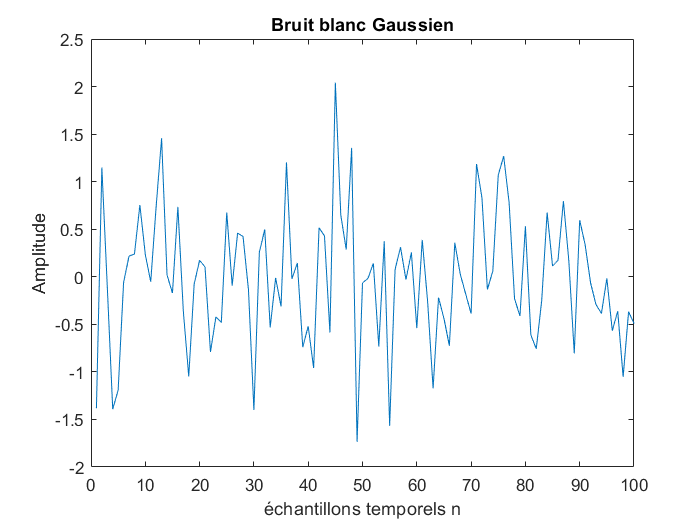


% plot(VectN, Sin)
% xlim([0, 100])
% xlabel("échantillons temporels n")
% ylabel("Amplitude")
% title("Signal sinusoïdale")


BruitB = BruitBlanc(N, sigmaCarre);


plot(VectN, BruitB)
xlim([0, 100])
xlabel("échantillons temporels n")
ylabel("Amplitude")
title("Bruit blanc Gaussien")


BBfiltreParAR1 = AR1(a, BruitB)

BBfiltreParAR1 =    -1.3828    0.4572    0.1229   -1.3303   -1.8574   -0.9902   -0.2777    0.0998    0.8044    0.6376    0.2668    0.8743    1.8930    0.9654    0.3126    0.8906    0.0866   -1.0054   -0.5780   -0.1156    0.0453   -0.7680   -0.8061   -0.8835    0.2336    0.0243    0.4713    0.6589    0.1933   -1.3040   -0.3954    0.3001   -0.3821   -0.2030   -0.4138    0.9961    0.4764    0.3824   -0.5497   -0.7948   -1.3567   -0.1631    0.3478   -0.4118    1.8360    1.5679    1.0709    1.8904   -0.7912   -0.4600


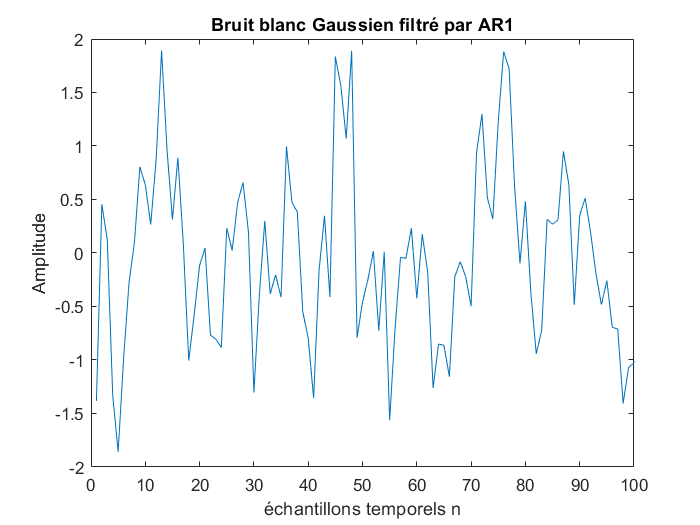


plot(VectN, BBfiltreParAR1)
xlim([0, 100])
xlabel("échantillons temporels n")
ylabel("Amplitude")
title("Bruit blanc Gaussien filtré par AR1")

Test de BiasedCrossCorr et UnbiasedCrossCorr

Sin


[AutoBiased, pVect1] = BiasedCrossCorr(Sin)

AutoBiased =     2.0239    1.9198    1.6293    1.1821    0.6232    0.0078   -0.6035   -1.1512   -1.5822   -1.8556   -1.9458   -1.8455   -1.5661   -1.1362   -0.5990   -0.0078    0.5794    1.1053    1.5190    1.7813    1.8677    1.7712    1.5029    1.0903    0.5749    0.0078   -0.5553   -1.0594   -1.4558   -1.7070   -1.7895   -1.6969   -1.4397   -1.0444   -0.5507   -0.0078    0.5311    1.0134    1.3926    1.6327    1.7114    1.6226    1.3765    0.9985    0.5266    0.0078   -0.5070   -0.9675   -1.3294   -1.5584


pVect1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


[AutoNbiased, pVect2] = UnbiasedCrossCorr(Sin)

AutoNbiased =     2.0239    1.9274    1.6421    1.1962    0.6330    0.0079   -0.6180   -1.1836   -1.6333   -1.9232   -2.0249   -1.9284   -1.6431   -1.1970   -0.6337   -0.0083    0.6180    1.1839    1.6339    1.9241    2.0259    1.9295    1.6442    1.1979    0.6343    0.0086   -0.6180   -1.1843   -1.6346   -1.9251   -2.0271   -1.9307   -1.6454   -1.1989   -0.6351   -0.0090    0.6180    1.1847    1.6354    1.9261    2.0283    1.9320    1.6466    1.2000    0.6359    0.0094   -0.6180   -1.1851   -1.6362   -1.9273


pVect2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



AutoTheo=[]


AutoTheo =

     []



for n = 0:N-1
    Auto = 2*cos(2*pi*Nu0*n)
    AutoTheo = [AutoTheo, Auto]
end

Auto = 2

AutoTheo = 2

Auto = 1.9021

AutoTheo =     2.0000    1.9021


Auto = 1.6180

AutoTheo =     2.0000    1.9021    1.6180


Auto = 1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756


Auto = 0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180


Auto = 1.2246e-16

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000


Auto = -0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180


Auto = -1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756


Auto = -1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180


Auto = -1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000


Auto = -1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021


Auto = -1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180


Auto = -1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756


Auto = -0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180


Auto = -3.6739e-16

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000


Auto = 0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180


Auto = 1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756


Auto = 1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180


Auto = 1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021


Auto = 2

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000


Auto = 1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021


Auto = 1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180


Auto = 1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756


Auto = 0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180


Auto = 6.1232e-16

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000


Auto = -0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180


Auto = -1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756


Auto = -1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180


Auto = -1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000


Auto = -1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021


Auto = -1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180


Auto = -1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756


Auto = -0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180


Auto = -8.5725e-16

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000


Auto = 0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180


Auto = 1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756


Auto = 1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180


Auto = 1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021


Auto = 2

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000


Auto = 1.9021

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021


Auto = 1.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180


Auto = 1.1756

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756


Auto = 0.6180

AutoTheo =     2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180


Auto = 1.1022e-15

AutoTheo = 1×46
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×47
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×48
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×49
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×50
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×51
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×52
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×53
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×54
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×55
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -4.8998e-15

AutoTheo = 1×56
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×57
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×58
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×59
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×60
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×61
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×62
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×63
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×64
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×65
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9607e-15

AutoTheo = 1×66
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×67
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×68
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×69
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×70
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×71
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×72
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×73
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×74
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×75
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -5.3897e-15

AutoTheo = 1×76
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×77
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×78
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×79
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×80
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×81
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×82
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×83
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×84
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×85
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.4708e-15

AutoTheo = 1×86
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×87
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×88
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×89
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×90
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×91
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×92
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×93
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×94
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×95
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -5.8795e-15

AutoTheo = 1×96
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×97
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×98
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×99
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×100
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×101
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×102
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×103
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×104
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×105
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -9.8096e-16

AutoTheo = 1×106
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×107
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×108
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×109
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×110
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×111
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×112
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×113
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×114
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×115
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -6.3694e-15

AutoTheo = 1×116
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×117
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×118
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×119
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×120
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×121
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×122
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×123
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×124
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×125
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -4.9110e-16

AutoTheo = 1×126
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×127
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×128
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×129
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×130
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×131
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×132
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×133
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×134
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×135
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -6.8593e-15

AutoTheo = 1×136
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×137
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×138
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×139
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×140
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×141
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×142
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×143
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×144
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×145
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.2380e-18

AutoTheo = 1×146
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×147
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×148
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×149
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×150
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×151
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×152
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×153
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×154
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×155
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -7.3491e-15

AutoTheo = 1×156
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×157
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×158
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×159
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×160
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×161
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×162
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×163
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×164
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×165
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 4.8862e-16

AutoTheo = 1×166
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×167
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×168
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×169
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×170
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×171
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×172
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×173
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×174
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×175
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -7.8390e-15

AutoTheo = 1×176
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×177
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×178
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×179
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×180
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×181
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×182
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×183
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×184
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×185
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 9.7848e-16

AutoTheo = 1×186
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×187
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×188
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×189
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×190
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×191
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×192
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×193
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×194
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×195
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -8.3288e-15

AutoTheo = 1×196
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×197
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×198
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×199
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×200
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×201
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×202
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×203
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×204
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×205
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.5679e-14

AutoTheo = 1×206
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×207
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×208
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×209
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×210
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×211
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×212
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×213
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×214
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×215
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -8.8187e-15

AutoTheo = 1×216
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×217
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×218
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×219
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×220
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×221
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×222
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×223
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×224
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×225
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9582e-15

AutoTheo = 1×226
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×227
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×228
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×229
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×230
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×231
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×232
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×233
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×234
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×235
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 4.9023e-15

AutoTheo = 1×236
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×237
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×238
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×239
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×240
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 2

AutoTheo = 1×241
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.9021

AutoTheo = 1×242
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6180

AutoTheo = 1×243
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.1756

AutoTheo = 1×244
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 0.6180

AutoTheo = 1×245
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = 1.6659e-14

AutoTheo = 1×246
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×247
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×248
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×249
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×250
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -2

AutoTheo = 1×251
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.9021

AutoTheo = 1×252
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.6180

AutoTheo = 1×253
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -1.1756

AutoTheo = 1×254
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -0.6180

AutoTheo = 1×255
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


Auto = -9.7984e-15

AutoTheo = 1×256
    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021


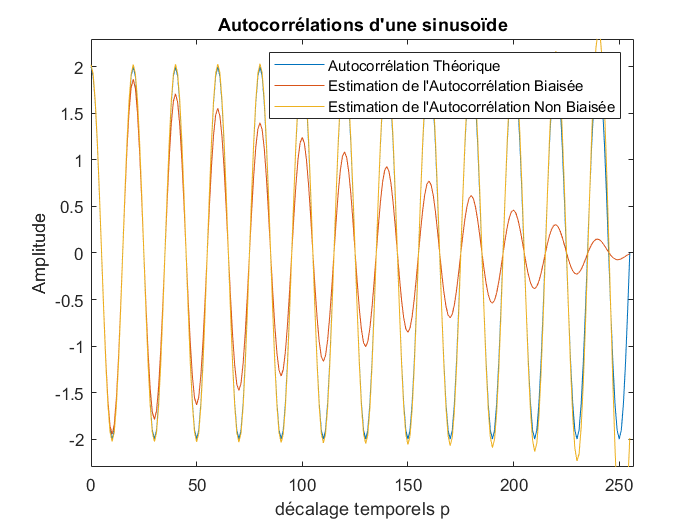



plot(pVect1, AutoTheo)

hold on
plot(pVect1, AutoBiased)

xlabel("décalage temporels p")
ylabel("Amplitude")
xlim([0, 257])
ylim([-2.3, 2.3])
%title("Estimation de l'Autocorrélation Biaisée")



plot(pVect2, AutoNbiased)

hold off


title("Autocorrélations d'une sinusoïde")
legend("Autocorrélation Théorique", "Estimation de l'Autocorrélation Biaisée", "Estimation de l'Autocorrélation Non Biaisée")

Bruit Blanc


[AutoBiasedBB, pVect1BB] = BiasedCrossCorr(BruitB)

AutoBiasedBB = 1×256
    0.4470    0.0064   -0.0301    0.0544   -0.0242   -0.0411   -0.0102   -0.0006   -0.0889   -0.0520   -0.0036   -0.0296   -0.0155   -0.0021   -0.0061   -0.0144    0.0516    0.0482    0.0145    0.0257    0.0250   -0.0408   -0.0399    0.0153   -0.0352   -0.0131   -0.0143   -0.0146   -0.0220    0.0342


pVect1BB = 1×256
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


[AutoNbiasedBB, pVect2BB] = UnbiasedCrossCorr(BruitB)

AutoNbiasedBB = 1×256
    0.4470    0.0064   -0.0304    0.0550   -0.0246   -0.0419   -0.0105   -0.0006   -0.0918   -0.0539   -0.0038   -0.0309   -0.0162   -0.0022   -0.0065   -0.0153    0.0551    0.0517    0.0156    0.0278    0.0271   -0.0445   -0.0437    0.0168   -0.0388   -0.0145   -0.0159   -0.0163   -0.0247    0.0386


pVect2BB = 1×256
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29



AutoTheo2= zeros(1, N)

AutoTheo2 = 1×256
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


AutoTheo2(1)=sigmaCarre

AutoTheo2 = 1×256
    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


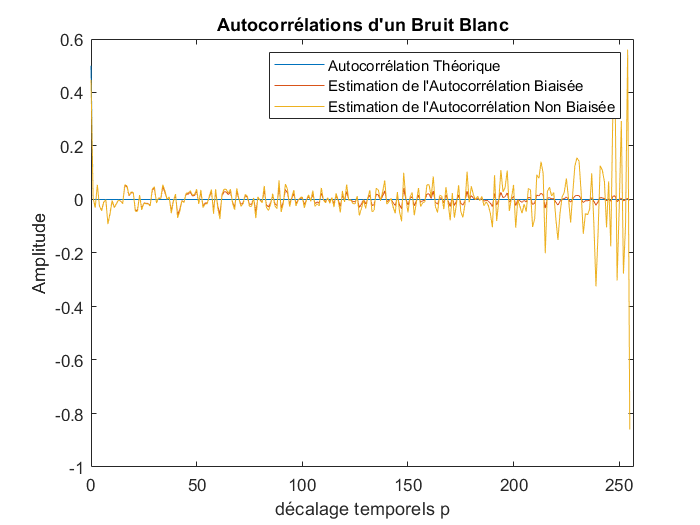



plot(pVect1BB, AutoTheo2)

hold on
plot(pVect1BB, AutoBiasedBB)

xlabel("décalage temporels p")
ylabel("Amplitude")
xlim([0, 257])
%ylim([-2.3, 2.3])
%title("Estimation de l'Autocorrélation Biaisée")



plot(pVect2BB, AutoNbiasedBB)

hold off


title("Autocorrélations d'un Bruit Blanc")
legend("Autocorrélation Théorique", "Estimation de l'Autocorrélation Biaisée", "Estimation de l'Autocorrélation Non Biaisée")

AR1

[AutoBiasedAR1, pVect1AR1] = BiasedCrossCorr(BBfiltreParAR1)

AutoBiasedAR1 = 1×256
    0.5932    0.2943    0.1308    0.0926   -0.0082   -0.0646   -0.0729   -0.0979   -0.1688   -0.1468   -0.0951   -0.0838   -0.0574   -0.0278   -0.0069    0.0233    0.0936    0.1072    0.0785    0.0614    0.0247   -0.0495   -0.0681   -0.0419   -0.0678   -0.0574   -0.0484   -0.0355   -0.0119    0.0491


pVect1AR1 = 1×256
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


[AutoNbiasedAR1, pVect2AR1] = UnbiasedCrossCorr(BBfiltreParAR1)

AutoNbiasedAR1 = 1×256
    0.5932    0.2955    0.1319    0.0937   -0.0084   -0.0659   -0.0746   -0.1006   -0.1743   -0.1522   -0.0990   -0.0875   -0.0603   -0.0293   -0.0073    0.0248    0.0999    0.1148    0.0844    0.0663    0.0268   -0.0539   -0.0745   -0.0460   -0.0748   -0.0636   -0.0539   -0.0396   -0.0134    0.0553


pVect2AR1 = 1×256
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29



AutoTheo3= []


AutoTheo3 =

     []



for n = 0:N-1
    Auto3 = sigmaCarre*a^n/(1-a^2)
    AutoTheo3 = [AutoTheo3, Auto3]
end

Auto3 = 0.6667

AutoTheo3 = 0.6667

Auto3 = 0.3333

AutoTheo3 = 1×2
    0.6667    0.3333


Auto3 = 0.1667

AutoTheo3 = 1×3
    0.6667    0.3333    0.1667


Auto3 = 0.0833

AutoTheo3 = 1×4
    0.6667    0.3333    0.1667    0.0833


Auto3 = 0.0417

AutoTheo3 = 1×5
    0.6667    0.3333    0.1667    0.0833    0.0417


Auto3 = 0.0208

AutoTheo3 = 1×6
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208


Auto3 = 0.0104

AutoTheo3 = 1×7
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104


Auto3 = 0.0052

AutoTheo3 = 1×8
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052


Auto3 = 0.0026

AutoTheo3 = 1×9
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026


Auto3 = 0.0013

AutoTheo3 = 1×10
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013


Auto3 = 6.5104e-04

AutoTheo3 = 1×11
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007


Auto3 = 3.2552e-04

AutoTheo3 = 1×12
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003


Auto3 = 1.6276e-04

AutoTheo3 = 1×13
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002


Auto3 = 8.1380e-05

AutoTheo3 = 1×14
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001


Auto3 = 4.0690e-05

AutoTheo3 = 1×15
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000


Auto3 = 2.0345e-05

AutoTheo3 = 1×16
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000


Auto3 = 1.0173e-05

AutoTheo3 = 1×17
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000


Auto3 = 5.0863e-06

AutoTheo3 = 1×18
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.5431e-06

AutoTheo3 = 1×19
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2716e-06

AutoTheo3 = 1×20
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.3578e-07

AutoTheo3 = 1×21
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.1789e-07

AutoTheo3 = 1×22
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5895e-07

AutoTheo3 = 1×23
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.9473e-08

AutoTheo3 = 1×24
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.9736e-08

AutoTheo3 = 1×25
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9868e-08

AutoTheo3 = 1×26
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.9341e-09

AutoTheo3 = 1×27
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.9671e-09

AutoTheo3 = 1×28
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.4835e-09

AutoTheo3 = 1×29
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2418e-09

AutoTheo3 = 1×30
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.2088e-10

AutoTheo3 = 1×31
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.1044e-10

AutoTheo3 = 1×32
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5522e-10

AutoTheo3 = 1×33
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.7610e-11

AutoTheo3 = 1×34
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.8805e-11

AutoTheo3 = 1×35
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9403e-11

AutoTheo3 = 1×36
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.7013e-12

AutoTheo3 = 1×37
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.8506e-12

AutoTheo3 = 1×38
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.4253e-12

AutoTheo3 = 1×39
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2127e-12

AutoTheo3 = 1×40
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.0633e-13

AutoTheo3 = 1×41
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.0316e-13

AutoTheo3 = 1×42
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5158e-13

AutoTheo3 = 1×43
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.5791e-14

AutoTheo3 = 1×44
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.7896e-14

AutoTheo3 = 1×45
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8948e-14

AutoTheo3 = 1×46
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.4739e-15

AutoTheo3 = 1×47
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.7370e-15

AutoTheo3 = 1×48
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3685e-15

AutoTheo3 = 1×49
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1842e-15

AutoTheo3 = 1×50
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.9212e-16

AutoTheo3 = 1×51
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.9606e-16

AutoTheo3 = 1×52
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4803e-16

AutoTheo3 = 1×53
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.4015e-17

AutoTheo3 = 1×54
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.7007e-17

AutoTheo3 = 1×55
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8504e-17

AutoTheo3 = 1×56
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.2519e-18

AutoTheo3 = 1×57
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.6259e-18

AutoTheo3 = 1×58
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3130e-18

AutoTheo3 = 1×59
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1565e-18

AutoTheo3 = 1×60
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.7824e-19

AutoTheo3 = 1×61
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.8912e-19

AutoTheo3 = 1×62
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4456e-19

AutoTheo3 = 1×63
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.2280e-20

AutoTheo3 = 1×64
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.6140e-20

AutoTheo3 = 1×65
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8070e-20

AutoTheo3 = 1×66
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.0350e-21

AutoTheo3 = 1×67
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.5175e-21

AutoTheo3 = 1×68
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.2588e-21

AutoTheo3 = 1×69
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1294e-21

AutoTheo3 = 1×70
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.6469e-22

AutoTheo3 = 1×71
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.8234e-22

AutoTheo3 = 1×72
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4117e-22

AutoTheo3 = 1×73
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.0586e-23

AutoTheo3 = 1×74
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.5293e-23

AutoTheo3 = 1×75
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.7647e-23

AutoTheo3 = 1×76
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.8233e-24

AutoTheo3 = 1×77
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.4116e-24

AutoTheo3 = 1×78
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.2058e-24

AutoTheo3 = 1×79
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1029e-24

AutoTheo3 = 1×80
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.5145e-25

AutoTheo3 = 1×81
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.7573e-25

AutoTheo3 = 1×82
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3786e-25

AutoTheo3 = 1×83
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.8932e-26

AutoTheo3 = 1×84
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.4466e-26

AutoTheo3 = 1×85
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.7233e-26

AutoTheo3 = 1×86
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.6165e-27

AutoTheo3 = 1×87
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.3082e-27

AutoTheo3 = 1×88
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.1541e-27

AutoTheo3 = 1×89
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0771e-27

AutoTheo3 = 1×90
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.3853e-28

AutoTheo3 = 1×91
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.6926e-28

AutoTheo3 = 1×92
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3463e-28

AutoTheo3 = 1×93
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.7316e-29

AutoTheo3 = 1×94
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.3658e-29

AutoTheo3 = 1×95
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6829e-29

AutoTheo3 = 1×96
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.4145e-30

AutoTheo3 = 1×97
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.2073e-30

AutoTheo3 = 1×98
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.1036e-30

AutoTheo3 = 1×99
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0518e-30

AutoTheo3 = 1×100
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.2591e-31

AutoTheo3 = 1×101
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.6295e-31

AutoTheo3 = 1×102
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3148e-31

AutoTheo3 = 1×103
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.5738e-32

AutoTheo3 = 1×104
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.2869e-32

AutoTheo3 = 1×105
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6435e-32

AutoTheo3 = 1×106
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.2173e-33

AutoTheo3 = 1×107
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.1087e-33

AutoTheo3 = 1×108
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.0543e-33

AutoTheo3 = 1×109
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0272e-33

AutoTheo3 = 1×110
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.1358e-34

AutoTheo3 = 1×111
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.5679e-34

AutoTheo3 = 1×112
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2840e-34

AutoTheo3 = 1×113
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.4198e-35

AutoTheo3 = 1×114
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.2099e-35

AutoTheo3 = 1×115
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6049e-35

AutoTheo3 = 1×116
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.0247e-36

AutoTheo3 = 1×117
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.0124e-36

AutoTheo3 = 1×118
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.0062e-36

AutoTheo3 = 1×119
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0031e-36

AutoTheo3 = 1×120
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.0154e-37

AutoTheo3 = 1×121
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.5077e-37

AutoTheo3 = 1×122
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2539e-37

AutoTheo3 = 1×123
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.2693e-38

AutoTheo3 = 1×124
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.1347e-38

AutoTheo3 = 1×125
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5673e-38

AutoTheo3 = 1×126
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.8366e-39

AutoTheo3 = 1×127
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.9183e-39

AutoTheo3 = 1×128
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9592e-39

AutoTheo3 = 1×129
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.7958e-40

AutoTheo3 = 1×130
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.8979e-40

AutoTheo3 = 1×131
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.4489e-40

AutoTheo3 = 1×132
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2245e-40

AutoTheo3 = 1×133
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.1224e-41

AutoTheo3 = 1×134
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.0612e-41

AutoTheo3 = 1×135
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5306e-41

AutoTheo3 = 1×136
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.6530e-42

AutoTheo3 = 1×137
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.8265e-42

AutoTheo3 = 1×138
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9132e-42

AutoTheo3 = 1×139
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.5662e-43

AutoTheo3 = 1×140
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.7831e-43

AutoTheo3 = 1×141
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3915e-43

AutoTheo3 = 1×142
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1958e-43

AutoTheo3 = 1×143
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.9789e-44

AutoTheo3 = 1×144
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.9894e-44

AutoTheo3 = 1×145
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4947e-44

AutoTheo3 = 1×146
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.4736e-45

AutoTheo3 = 1×147
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.7368e-45

AutoTheo3 = 1×148
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8684e-45

AutoTheo3 = 1×149
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.3420e-46

AutoTheo3 = 1×150
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.6710e-46

AutoTheo3 = 1×151
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3355e-46

AutoTheo3 = 1×152
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1677e-46

AutoTheo3 = 1×153
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.8387e-47

AutoTheo3 = 1×154
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.9194e-47

AutoTheo3 = 1×155
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4597e-47

AutoTheo3 = 1×156
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.2984e-48

AutoTheo3 = 1×157
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.6492e-48

AutoTheo3 = 1×158
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8246e-48

AutoTheo3 = 1×159
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.1230e-49

AutoTheo3 = 1×160
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.5615e-49

AutoTheo3 = 1×161
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.2808e-49

AutoTheo3 = 1×162
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1404e-49

AutoTheo3 = 1×163
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.7019e-50

AutoTheo3 = 1×164
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.8509e-50

AutoTheo3 = 1×165
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4255e-50

AutoTheo3 = 1×166
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.1274e-51

AutoTheo3 = 1×167
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.5637e-51

AutoTheo3 = 1×168
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.7818e-51

AutoTheo3 = 1×169
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.9092e-52

AutoTheo3 = 1×170
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.4546e-52

AutoTheo3 = 1×171
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.2273e-52

AutoTheo3 = 1×172
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1137e-52

AutoTheo3 = 1×173
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.5683e-53

AutoTheo3 = 1×174
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.7841e-53

AutoTheo3 = 1×175
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3921e-53

AutoTheo3 = 1×176
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.9603e-54

AutoTheo3 = 1×177
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.4802e-54

AutoTheo3 = 1×178
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.7401e-54

AutoTheo3 = 1×179
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.7004e-55

AutoTheo3 = 1×180
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.3502e-55

AutoTheo3 = 1×181
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.1751e-55

AutoTheo3 = 1×182
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0876e-55

AutoTheo3 = 1×183
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.4378e-56

AutoTheo3 = 1×184
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.7189e-56

AutoTheo3 = 1×185
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3594e-56

AutoTheo3 = 1×186
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.7972e-57

AutoTheo3 = 1×187
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.3986e-57

AutoTheo3 = 1×188
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6993e-57

AutoTheo3 = 1×189
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.4965e-58

AutoTheo3 = 1×190
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.2482e-58

AutoTheo3 = 1×191
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.1241e-58

AutoTheo3 = 1×192
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0621e-58

AutoTheo3 = 1×193
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.3103e-59

AutoTheo3 = 1×194
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.6552e-59

AutoTheo3 = 1×195
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.3276e-59

AutoTheo3 = 1×196
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.6379e-60

AutoTheo3 = 1×197
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.3189e-60

AutoTheo3 = 1×198
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6595e-60

AutoTheo3 = 1×199
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.2974e-61

AutoTheo3 = 1×200
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.1487e-61

AutoTheo3 = 1×201
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.0743e-61

AutoTheo3 = 1×202
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0372e-61

AutoTheo3 = 1×203
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.1858e-62

AutoTheo3 = 1×204
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.5929e-62

AutoTheo3 = 1×205
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2965e-62

AutoTheo3 = 1×206
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.4823e-63

AutoTheo3 = 1×207
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.2412e-63

AutoTheo3 = 1×208
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.6206e-63

AutoTheo3 = 1×209
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 8.1029e-64

AutoTheo3 = 1×210
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.0514e-64

AutoTheo3 = 1×211
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.0257e-64

AutoTheo3 = 1×212
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.0129e-64

AutoTheo3 = 1×213
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.0643e-65

AutoTheo3 = 1×214
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.5322e-65

AutoTheo3 = 1×215
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2661e-65

AutoTheo3 = 1×216
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.3304e-66

AutoTheo3 = 1×217
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.1652e-66

AutoTheo3 = 1×218
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5826e-66

AutoTheo3 = 1×219
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.9130e-67

AutoTheo3 = 1×220
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.9565e-67

AutoTheo3 = 1×221
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9782e-67

AutoTheo3 = 1×222
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.8912e-68

AutoTheo3 = 1×223
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.9456e-68

AutoTheo3 = 1×224
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.4728e-68

AutoTheo3 = 1×225
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2364e-68

AutoTheo3 = 1×226
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.1820e-69

AutoTheo3 = 1×227
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.0910e-69

AutoTheo3 = 1×228
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5455e-69

AutoTheo3 = 1×229
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.7275e-70

AutoTheo3 = 1×230
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.8638e-70

AutoTheo3 = 1×231
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.9319e-70

AutoTheo3 = 1×232
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.6594e-71

AutoTheo3 = 1×233
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.8297e-71

AutoTheo3 = 1×234
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.4148e-71

AutoTheo3 = 1×235
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.2074e-71

AutoTheo3 = 1×236
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 6.0371e-72

AutoTheo3 = 1×237
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.0186e-72

AutoTheo3 = 1×238
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.5093e-72

AutoTheo3 = 1×239
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.5464e-73

AutoTheo3 = 1×240
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.7732e-73

AutoTheo3 = 1×241
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8866e-73

AutoTheo3 = 1×242
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.4330e-74

AutoTheo3 = 1×243
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.7165e-74

AutoTheo3 = 1×244
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3582e-74

AutoTheo3 = 1×245
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1791e-74

AutoTheo3 = 1×246
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 5.8956e-75

AutoTheo3 = 1×247
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.9478e-75

AutoTheo3 = 1×248
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.4739e-75

AutoTheo3 = 1×249
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 7.3695e-76

AutoTheo3 = 1×250
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 3.6848e-76

AutoTheo3 = 1×251
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.8424e-76

AutoTheo3 = 1×252
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 9.2119e-77

AutoTheo3 = 1×253
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 4.6060e-77

AutoTheo3 = 1×254
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 2.3030e-77

AutoTheo3 = 1×255
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Auto3 = 1.1515e-77

AutoTheo3 = 1×256
    0.6667    0.3333    0.1667    0.0833    0.0417    0.0208    0.0104    0.0052    0.0026    0.0013    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


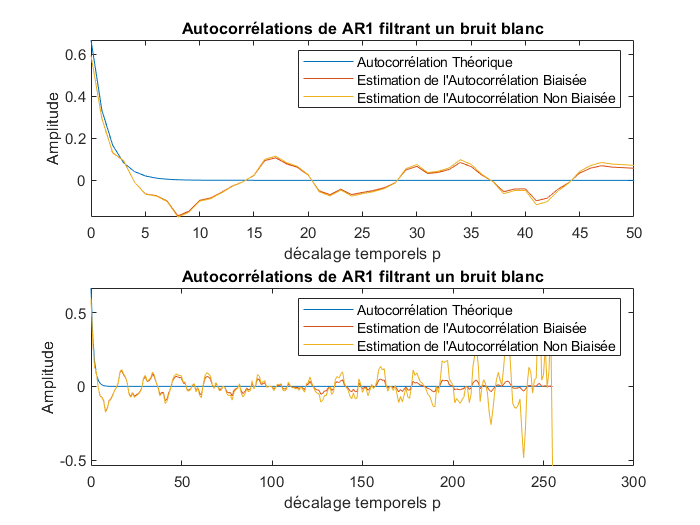


figure(1)
subplot(211)

plot(pVect1AR1, AutoTheo3)

hold on
plot(pVect1AR1, AutoBiasedAR1)

xlabel("décalage temporels p")
ylabel("Amplitude")
xlim([0, 50])
%ylim([-2.3, 2.3])
%title("Estimation de l'Autocorrélation Biaisée")



plot(pVect2AR1, AutoNbiasedAR1)

hold off


title("Autocorrélations de AR1 filtrant un bruit blanc")
legend("Autocorrélation Théorique", "Estimation de l'Autocorrélation Biaisée", "Estimation de l'Autocorrélation Non Biaisée")

subplot(212)

plot(pVect1AR1, AutoTheo3)

hold on
plot(pVect1AR1, AutoBiasedAR1)

xlabel("décalage temporels p")
ylabel("Amplitude")
%xlim([0, 50])
%ylim([-2.3, 2.3])
%title("Estimation de l'Autocorrélation Biaisée")



plot(pVect2AR1, AutoNbiasedAR1)

hold off


title("Autocorrélations de AR1 filtrant un bruit blanc")
legend("Autocorrélation Théorique", "Estimation de l'Autocorrélation Biaisée", "Estimation de l'Autocorrélation Non Biaisée")


[MaxSin, position] = max(AutoBiased(25 : 100))

MaxSin = 1.7114

position = 17


ValSin = MaxSin/AutoBiased(1)

ValSin = 0.8456

[MaxBB, position2] = max(AutoBiasedBB(25 : 100))

MaxBB = 0.0478

position2 = 11


ValBB = MaxBB/AutoBiasedBB(1)

ValBB = 0.1069


[MaxAR1, position3] = max(AutoBiasedAR1(25 : 100))

MaxAR1 = 0.0848

position3 = 11


ValAR1 = MaxAR1/AutoBiasedAR1(1)

ValAR1 = 0.1430

boolSin = isVoiced(AutoBiased)

boolSin = 1

boolBB = isVoiced(AutoBiasedBB)

boolBB = 0

boolAR1 = isVoiced(AutoBiasedAR1)

boolAR1 = 0